# Paper2 Fig3: investigate smearing fields

## Setting up WS

CurrentFolder = pwd
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2
DataFolder2 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/Typical_trajs/']; % V1D2

addpath(DataFolder2)
addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))

close all

SaveFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/SmearInvestigation/'];

Lists of truncations

smFctL6List = repmat([.3 .4 .5 .5],1,2);
smFctLGNList = repmat([.2 .2 .2 .3],1,2);
TruncL6List = [ones(1,4), ones(1,4)*1.25];
TruncLGN = 1;

## 2. Set up LDE firing rate functions

first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};
DomList =  {'Small','Large','Larger','LARGER'};


Choose from the list, but input can take everything between 0-180

for AngleInpt = 0:7.5:22.5% has to be multiples of 7.5
    RotInd = floor(AngleInpt/45); % 0-3
    MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
    switch MirInd % find the corresponding source
        case 0
            AngSource = mod(AngleInpt,45);
        case 1
            AngSource = mod(-AngleInpt,45);
    end
    MirInd = logical(MirInd);
    % Use the source, decide which response function for angle should I use
    AngFuncCtgrCdid = 0:7.5:22.5;
    [~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));
    
    AngPrint = AngleList{AngFuncCtgr};
    Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5

load all precomputed domains

    L4EmeshXAll = cell(size(DomList));
    L4ImeshYAll = cell(size(DomList));
    LDEFrfuncAll = cell(size(DomList));
    for DomInd = 1:length(DomList)
        FuncTemp = load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{DomInd}),...
            'LDEFrfunc','L4EmeshX','L4ImeshY');
        L4EmeshXAll{DomInd} = FuncTemp.L4EmeshX;
        L4ImeshYAll{DomInd} = FuncTemp.L4ImeshY;
        LDEFrfuncAll{DomInd} = FuncTemp.LDEFrfunc;
    end
    

## 3. Set up initial conditions

    N_HCOut = 4; NPixX = 10; NPixY = 10;
    

%%%60 deg: by rotating 15 deg pattern

Start from 90, then go to 22.5

    ICData = load([DataFolder2 sprintf('LDETracesV4D2_New_ang0.0.mat')]);
    
    LDEICPart = ICData.LDEOutAll{1}{end};
    LDEICPart = HCRot(LDEICPart,0,N_HCOut,NPixX,NPixY,0);
    
    ICUse = LDEICPart;
    IniTest.S = symmHCs(ICUse.S,N_HCOut,NPixX,NPixY);
    IniTest.C = symmHCs(ICUse.C,N_HCOut,NPixX,NPixY);
    IniTest.I = symmHCs(ICUse.I,N_HCOut,NPixX,NPixY);

load equiv

    %PlotUse = load([DataFolder2 sprintf('LDETraces_bg-ang%s.mat',AngPrint)],'LDEEquv');
    %LDEEquv = PlotUse.LDEEquv;
    %LDEEquv = HCRot(LDEEquv,RotInd,N_HCOut,NPixX,NPixY,MirInd);

## 4. Iteration 

New: Need to extend all these to arbitrary HC numbers!

    N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
    LGNlist = 4; L6list = 4;

LGN and L6 are blurred 

## Note: This small subsec is unused. And should be cos instead of sin

    Grating = Angle; % degree
    GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
    LGNS_biphase = [45+abs(mod(GratingHC,180)-90)/2;
        45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;
    
    FigOn = true;
    L6Ord_F_Grating = min(L6Ord_F) + ...
        (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
    L6S_Drive_Grating = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;
    L6C_Drive_Grating = L6Ord_F_Grating*NC_L6/1e3 * StimulusFac; % only for investigation purpose

    
    EquvAll = cell(length(smFctL6List),1);
    parfor SmInd = 1:length(smFctLGNList)
        LDEOutAll = cell(size(LDEICPart));
        smFctL6 = smFctL6List(SmInd);
        smFctLGN = smFctLGNList(SmInd);
        TruncL6 = TruncL6List(SmInd);
        
        L6smear = n_S_HC*smFctL6; LGNsmear = n_S_HC*smFctLGN;
        
        L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
            N_HC,n_S_HC,L6smear,TruncL6,FigOn);
        LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
            N_HC,n_S_HC,LGNsmear,TruncLGN,FigOn);
        
        PixL6Ctgr = LGNIndSpat(L6SFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
        PixLGNCtgr = LGNIndSpat(LGNFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

        for Ctgr = 1:4
            PixL6Ctgr(:,Ctgr) = HCRot(PixL6Ctgr(:,Ctgr),RotInd,N_HCOut,NPixX,NPixY,MirInd);
            PixLGNCtgr(:,Ctgr) = HCRot(PixLGNCtgr(:,Ctgr),RotInd,N_HCOut,NPixX,NPixY,MirInd);
        end
        
        PixInptCtgrUse  = zeros(PixNumOut,LGNlist,L6list);
        for PixInd = 1:PixNumOut
            PixInptCtgrUse(PixInd,:,:) = PixLGNCtgr(PixInd,:)' *PixL6Ctgr(PixInd,:);% by multiplying both indexes
        end

Get pixelwise connectivities

        C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
        C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);

start iteration

        p = 0.33;% 1-p for the original input
        EpocTest = 50;
        ExportFlag = 'xn';
        
        tic
        for TestInd = 1:length(LDEICPart)
            
            [LDEOutAll{TestInd},~,~,~,~,FuncUse] = ...
                LDEIteration_16FuncMain_CombDom(...
                PixInptCtgrUse,IniTest,p,EpocTest,...
                C_SS_mean,C_CS_mean,C_IS_mean,...
                C_SC_mean,C_CC_mean,C_IC_mean,...
                C_SI_mean,C_CI_mean,C_II_mean,...
                L4EmeshXAll,L4ImeshYAll,LDEFrfuncAll,...
                N_HCOut,NPixX,NPixY,false,'xn')  ;
            LDEEquv = LDEOutAll{TestInd}{end};
        end
        toc
        EquvAll{SmInd} = LDEEquv;
        % save([DataFolder2 sprintf('LDETracesV4D2_New_ang%s.mat',AngPrint)],...
        %     'LDEOutAll','LDEEquv','L2Diff_OneStepAll','DiffVecAll')
        
    end
    save([SaveFolder1 sprintf('smeartest_Angle%.1f.mat',Angle)],...
        'EquvAll','smFctL6List','smFctLGNList','TruncL6List','TruncLGN')
end


## 4. Compare response patterns

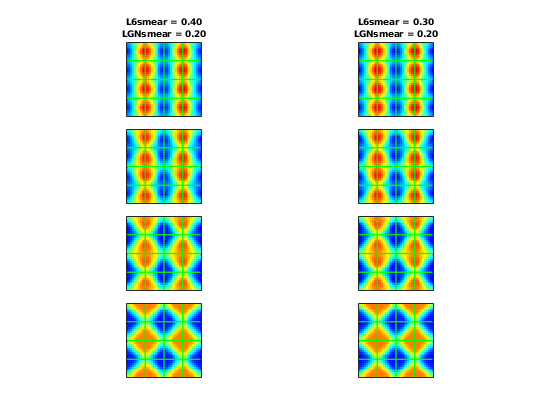

N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
Fig3 = figure("Name",'Different Smears');
%Panel1 = length(smFctL6List); Panel2 = length(AngleList);%length(EpocList);
Panel1 = 2; Panel2 = 4;%length(EpocList);
ha = tight_subplot(Panel2,Panel1,[.03 .03],[.1 .1],[.10 .10]);

plotind = 1;
for AngleInpt = 0:7.5:22.5
    DataUse = load([SaveFolder1 sprintf('smeartest_Angle%.1f.mat',AngleInpt)]);
    
    
    for SmInd = [2 5]
        LDEPlot = DataUse.EquvAll{SmInd};
        axes(ha(plotind));
        
        if AngleInpt == 0
            titleprt = sprintf('L6smear = %.2f\nLGNsmear = %.2f',...
                DataUse.smFctL6List(SmInd), DataUse.smFctLGNList(SmInd) );
        else
            titleprt = '';
        end
        ShowField(...
            LDEPlot.S*(1-CplxR)+LDEPlot.C*CplxR,...
            1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,...
            titleprt, [5 35]) % last input may catgorized cbar: ,, [5 60]
        set(gca,'fontsize',6)
        set(gca,'YTickLabel',[]);
        set(gca,'XTickLabel',[]);
        
        if SmInd == 1
            ylabel(sprintf('$$%.1f^\circ$$',AngleInpt),"Interpreter","latex")
        end
        colorbar off
        %axis([NPixX+.5 2*NPixX+.5 NPixX+.5 2*NPixY+.5])
        plotind = plotind+1;
    end
end


%subplot(2,6,EpocInd+6*(ICInd-1))


## 5. Compare tuning curves

N_HCOut = 4;
for SmInd = 1:length(DataUse.smFctL6List)
    for AngInd = 1:length(AngleList)
        FrTunCurAllPix = cell(NPixY,NPixX);
        for XX = 1:NPixX
            for YY = 1:NPixY
                FrTunCurAllPix{YY,XX}.S = zeros(8,1);
                FrTunCurAllPix{YY,XX}.C = zeros(8,1);
            end
        end
        
        AngPrint = AngleList{AngInd};
        PlotUse = load([SaveFolder1 sprintf('smeartest_Angle%s.mat',AngPrint)]);
        
        LDEOut = PlotUse.EquvAll{SmInd};
        LDEOutS = reshape(LDEOut.S,N_HCOut*NPixY,N_HCOut*NPixX);
        LDEOutC = reshape(LDEOut.C,N_HCOut*NPixY,N_HCOut*NPixX);
        %figure
        %ShowField(LDEOut.S*(1-CplxR) + LDEOut.C*CplxR,1:1600,40,40)
        for YInd = 1:NPixY
            for XInd = 1:NPixX
                y0 = NPixY+YInd; x0 = NPixX+XInd;
                % make sure this is in the center HC, so x0, y0 \in [11,20]
                %x0 = 11; y0 = 19; [13, 16] [14, 20]
                xC = NPixX*1.5+0.5; yC = NPixY*1.5+0.5;
                xx = x0-xC; yy = y0-yC; % centered
                RtPix = ...
                    [xx,yy;
                    yy,-xx;
                    -xx,-yy;
                    -yy,xx]; % rotational group
                SmPix = ...
                    [-yy,-xx;
                    -xx,yy;
                    yy,xx;
                    xx,-yy]; % Symmetry group
                PixAll = zeros(8,2);
                PixAll(1:2:7,:) = RtPix; PixAll(2:2:8,:) = SmPix;
                PixAllUse = floor(PixAll + repmat([xC,yC],8,1));
                for PixInd = 1:8
                    FrTunCurAllPix{YInd,XInd}.S(PixInd) = ...
                        LDEOutS(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
                    FrTunCurAllPix{YInd,XInd}.C(PixInd) = ...
                        LDEOutC(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
                end
            end
        end
        
        save([SaveFolder1 sprintf('FrTuneCurE_Ang%s_CosAll_Smtest%d.mat',AngPrint,SmInd)],...
            'FrTunCurAllPix')
    end
end

fig5CurveTest = figure('Name','fig5CurveTest');
cmap = colormap("jet");
TruncInd = 1;
for SmInd = 1:length(DataUse.smFctL6List)

        Any Pix

    % fisrt load all data
    FrTunCurveRawDataAll = cell(size(AngleList));
    AngleAll = zeros(size(AngleList));
    for AngInd = 1:length(AngleList)
        AngPrint = AngleList{AngInd};
        AngleAll(AngInd) = str2num(AngPrint);
        FrTunCurveRawDataAll{AngInd} = ...
            load([SaveFolder1 sprintf('FrTuneCurE_Ang%s_CosAll_Smtest%d.mat',AngPrint,SmInd)],...
            'FrTunCurAllPix');
    end
    

            clearThree categories of pixels

    [xAll,yAll] = meshgrid(1:10,1:10);
    PixCtgr = cell(1,1);
    xC = NPixX*.5+0.5; yC = NPixY*.5+0.5;% center
    % get pix index for each categories
    [PixCtgr{1}(:,1),PixCtgr{1}(:,2),~] = ...
        find( ...
        ( max(abs(xAll-xC),abs(yAll-yC)) == 4.5...%)); ...
        & max(abs(xAll-1), abs(yAll-1))>=2 ...
        & max(abs(xAll-NPixX), abs(yAll-NPixY))>=2 ...
        & max(abs(xAll-1), abs(yAll-NPixY))>=2 ...
        & max(abs(xAll-NPixX), abs(yAll-1))>=2));
    PixCtgr{1} = [
        PixCtgr{1};
        2,2;
        2,9;
        9,2;
        9,9];
    
    CtgrPix = PixCtgr{1};
    CtgrPix(CtgrPix(:,1)>5 | CtgrPix(:,2)<=5,:) = [];
    [~,a] = sort(CtgrPix(:,1)+CtgrPix(:,2));
    CtgrPix = CtgrPix(a,:);
    CtgrPix(2,:) = [];CtgrPix(end-1,:) = [];
    PixTxt = 'a':char('a'+length(CtgrPix)-1); % Text on the pixel
    MarkerList = {'*','o','+','x','s','^','p'};
    LW = [2,1/2,2,1/2,2,1/2,2];
    
    
    subplot(4,2,SmInd)
    hold on
    for PixInd = 1:length(CtgrPix)
        x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);      
        % get tuning curves
        [AngleData,TuningCurveTrunc,~,PreferAng] = TuningCurve(...
            1,AngleList,FrTunCurveRawDataAll,...
            x,y,AngleAll,NPixX,NPixY,cmap);
        AngleCenter = PreferAng*180;
       
        % get unique data
        AngleUnique = unique(AngleData);
        TuningCurveUnique.S = zeros(size(AngleUnique));
        TuningCurveUnique.C = zeros(size(AngleUnique));
        TuningCurvePlot.S = zeros(size(AngleUnique));
        TuningCurvePlot.C = zeros(size(AngleUnique));

            1. Smooth the pumps; 2. recenter curves to 0 deg

        for AngInd = 1:length(AngleUnique)
            Ang = AngleUnique(AngInd);
            TuningCurveUnique.S(AngInd) ...
                = mean(TuningCurveTrunc.S(AngleData==Ang,TruncInd),'all');
            TuningCurveUnique.C(AngInd) ...
                = mean(TuningCurveTrunc.C(AngleData==Ang,TruncInd),'all');
        end
        
        % note: length of AngleUnique should be odd!
        AnglePlot = [AngleUnique(floor(end/2)+1:end-1),...
            AngleUnique(1:floor(end/2)), ...
            AngleUnique(floor(end/2)+1)];
        for AngInd = 1:length(AnglePlot)
            Ang = AnglePlot(AngInd);
            TuningCurvePlot.S(AngInd) ...
                = mean(TuningCurveUnique.S(AngleUnique==Ang),'all');
            TuningCurvePlot.C(AngInd) ...
                = mean(TuningCurveUnique.C(AngleUnique==Ang),'all');
        end
        
        textPlot = mat2cell(repmat(PixTxt(PixInd),1,length(AngleUnique)),1,ones(size(AngleUnique)));
        
        plot(AngleUnique,TuningCurvePlot.S*0.7 + ...
            TuningCurvePlot.C*0.3,'k','LineWidth',LW(PixInd),...)
            ...% 'Color',TunCurColor,
            'DisplayName',PixTxt(PixInd),'Marker',MarkerList{PixInd})
        %     text(AngleUnique,TuningCurvePlot.S*0.7 + ...
        %         TuningCurvePlot.C*0.3-0.5,...
        %         textPlot, 'HorizontalAlignment','center', 'VerticalAlignment','bottom')
        
    end
    
    % set appropirate xticks and others
    xtickAng = AnglePlot;
    xtickLab = cell(size(xtickAng));
    for xticInd = 1:length(xtickAng)
        if mod(xticInd,2) == 1
            xtickLab{xticInd} = num2str(xtickAng(xticInd));
        end
    end
    
    xlabel('Grating Angle (deg)');
    ylabel('E firing rate')
    title(sprintf('L6smear = %.2f; LGNsmear = %.2f; L6Trunc = %.2f',...
                DataUse.smFctL6List(SmInd), DataUse.smFctLGNList(SmInd), TruncL6List(SmInd) ));
    
    ylim([6 36]); xlim([0 180])
    set(gca,'xtick',AngleUnique,'xticklabel',xtickLab)
    set(gca, 'FontSize',9)
    grid on
    %xlim([min(xtickAng) max(xtickAng)])
    legend('Location','northwest')
    
end